# Generative Adversarial Network (GAN)

Генеративно-состязательная сеть (GAN) — это тип сети глубокого обучения, которая может генерировать данные с такими же характеристиками, как и входные реальные данные.

Функция trainNetwork не поддерживает обучающие сети GAN, поэтому необходимо реализовать собственный цикл обучения.

Эта диаграмма иллюстрирует структуру GAN.

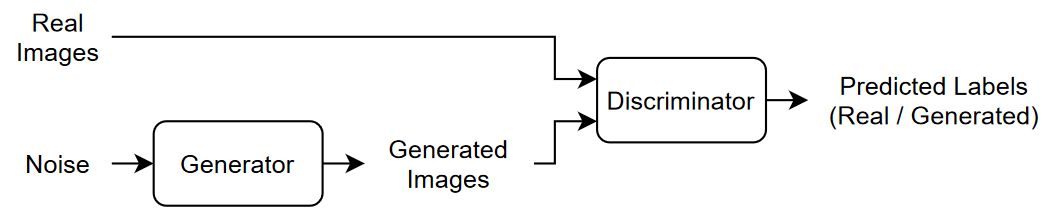

Чтобы обучить GAN, необхадимо обучать обе сети одновременно, чтобы максимизировать производительность обеих: 

- Обучить генератор генерировать данные, которые «обманывают» дискриминатор. 

- Обучитеь дискриминатор различать реальные и сгенерированные данные.

## Загрузка тренировочных данных

clear; clc;
imageFolder = ("img/bmp/bmp_2");%("img/png");

Создние хранилища данных изображений, содержащее фотографии.

imds = imageDatastore(imageFolder,IncludeSubfolders=true);

Увеличение выборки данных, заа счёт случайного горизонтального переворачивания, и измениние размера изображений.

augmenter = imageDataAugmenter(RandXReflection=true);
augimds = augmentedImageDatastore([354 379],imds,DataAugmentation=augmenter);

## Определение генеративно-состязательной сети.

filterSize = 5;
numFilters = 64;
numLatentInputs = 100;
projectionSize = [4 4 512];

layersGenerator = [
    featureInputLayer(numLatentInputs)
    projectAndReshapeLayer(projectionSize)
    transposedConv2dLayer(filterSize,4*numFilters)
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,2*numFilters,Stride=2,Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,numFilters,Stride=2,Cropping="same")
    batchNormalizationLayer
    reluLayer
    transposedConv2dLayer(filterSize,3,Stride=2,Cropping="same")
    tanhLayer];
netG = dlnetwork(layersGenerator);

### Определение сети дискриминатора

dropoutProb = 0.5;
numFilters = 64;
scale = 0.2;
inputSize = [372 230 3];
%     [354 379 3] png?
%     [232 260 3] bmp_1
%     [372 230 3] bmp_2
filterSize = 5;

layersDiscriminator = [
    imageInputLayer(inputSize,Normalization="none")
    dropoutLayer(dropoutProb)
    convolution2dLayer(filterSize,numFilters,Stride=2,Padding="same")
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,2*numFilters,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,4*numFilters,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(filterSize,8*numFilters,Stride=2,Padding="same")
    batchNormalizationLayer
    leakyReluLayer(scale)
    convolution2dLayer(4,1)
    sigmoidLayer];
netD = dlnetwork(layersDiscriminator);

## Параметры обучения.

numEpochs = 500;
miniBatchSize = 128;
learnRate = 0.0002;
gradientDecayFactor = 0.5;
squaredGradientDecayFactor = 0.999;
flipProb = 0.35;
validationFrequency = 100;

## Тренировка модели

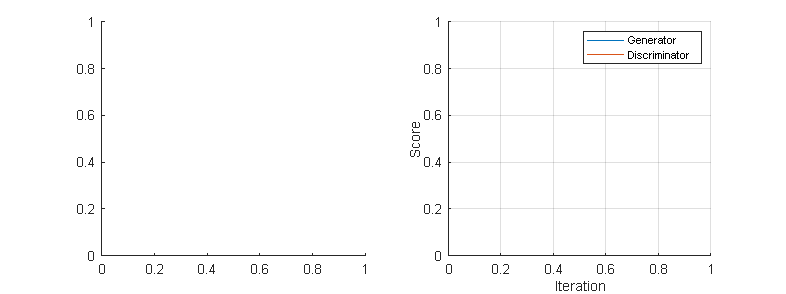

augimds.MiniBatchSize = miniBatchSize;
mbq = minibatchqueue(augimds, ...
    MiniBatchSize=miniBatchSize, ...
    PartialMiniBatch="discard", ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");
trailingAvgG = [];
trailingAvgSqG = [];
trailingAvg = [];
trailingAvgSqD = [];
numValidationImages = 25;
ZValidation = randn(numLatentInputs,numValidationImages,"single");
ZValidation = dlarray(ZValidation,"CB");
if canUseGPU
    ZValidation = gpuArray(ZValidation);
end
f = figure;
f.Position(3) = 2*f.Position(3);
imageAxes = subplot(1,2,1);
scoreAxes = subplot(1,2,2);
C = colororder;
lineScoreG = animatedline(scoreAxes,Color=C(1,:));
lineScoreD = animatedline(scoreAxes,Color=C(2,:));
legend("Generator","Discriminator");
ylim([0 1])
xlabel("Iteration")
ylabel("Score")
grid on

iteration = 0;
start = tic;
% Цикл по эпохам.
for epoch = 1:numEpochs
    % Сбросить и перетасовать хранилище данных.
    shuffle(mbq);
    % Цикл по мини-партиям.
    while hasdata(mbq)
        iteration = iteration + 1;
        % Чтение мини-пакета данных.
        X = next(mbq);
        X = dlarray((X),'SSCB');
        %  "CB" (канал, пакет).
        Z = randn(numLatentInputs,miniBatchSize,"single");
        Z = dlarray(Z,'CB');
        if canUseGPU
            Z = gpuArray(Z);
        end
        % Градиенты потерь
        [~,~,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
            dlfeval(@modelLoss,netG,netD,X,Z,flipProb);
        netG.State = stateG;
        % Обновление параметров дискриминатора.
        [netD,trailingAvg,trailingAvgSqD] = adamupdate(netD, gradientsD, ...
            trailingAvg, trailingAvgSqD, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        % Обновление параметров сети генератора.
        [netG,trailingAvgG,trailingAvgSqG] = adamupdate(netG, gradientsG, ...
            trailingAvgG, trailingAvgSqG, iteration, ...
            learnRate, gradientDecayFactor, squaredGradientDecayFactor);
        % Отображение сгенерированных изображений
        if mod(iteration,validationFrequency) == 0 || iteration == 1
            % Создание изображения
            XGeneratedValidation = predict(netG,ZValidation);
            I = imtile(extractdata(XGeneratedValidation));
            I = rescale(I);
            % Отобразите изображения.
            subplot(1,2,1);
            image(imageAxes,I)
            title("Сгенерированные изображения");
        end
        % Обновить график результатов.
        subplot(1,2,2)
        scoreG = double(extractdata(scoreG));
        addpoints(lineScoreG,iteration,scoreG);
        scoreD = double(extractdata(scoreD));
        addpoints(lineScoreD,iteration,scoreD);
        % Обновить заголовок с информацией.
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        title("Эпоха: " + epoch + ", " + ...
            "Итерация: " + iteration + ", " + ...
            "Время: " + string(D))
        drawnow
    end
end

Error using nnet.internal.cnn.layer.GraphExecutor/propagate
Layer 'leakyrelu_1': Invalid input data. Out of
memory on device. To view more detail about
available memory on the GPU, use 'gpuDevice()'. If
the problem persists, reset the GPU by calling
'gpuDevice(1)'.

Error in nnet.internal.cnn.layer.GraphExecutor/forwardPropagate (line 183)
            [varargout{1:nargout}] = this.propagate(propagateFcn, X, outputLayerIdx, outputLayerPortIdx);

Error in 

## Создание новых изображений.

numObservations = 25;
ZNew = randn(numLatentInputs,numObservations,"single");
ZNew = dlarray(ZNew,"CB");
if canUseGPU
    ZNew = gpuArray(ZNew);
end
XGeneratedNew = predict(netG,ZNew);
I = imtile(extractdata(XGeneratedNew));
I = rescale(I);
figure
image(I)
axis off
title("Generated Images")

## Функция потерь модели

Функция принимает на вход генератор и дискриминатор dlnetwork объектов netG и netD, мини-пакет входных данных X, массив случайных значений Z и вероятность перевернуть реальные метки flipProb, и возвращает значения потерь, градиенты значений потерь по отношению к обучаемым параметрам в сетях, состоянии генератора и оценкам двух сетей.

function [lossG,lossD,gradientsG,gradientsD,stateG,scoreG,scoreD] = ...
    modelLoss(netG,netD,X,Z,flipProb)
% Рассчитать прогнозы для реальных данных
YReal = forward(netD,X);
% Рассчитать прогнозы для сгенерированных данных
[XGenerated,stateG] = forward(netG,Z);
YGenerated = forward(netD,XGenerated);
% Рассчитайте оценку дискриминатора.
scoreD = (mean(YReal) + mean(1-YGenerated)) / 2;
% Рассчитать оценку генератора.
scoreG = mean(YGenerated);
% Произвольно перевернуть метки реальных изображений.
numObservations = size(YReal,4);
idx = rand(1,numObservations) < flipProb;
YReal(:,:,:,idx) = 1 - YReal(:,:,:,idx);
% Рассчитать потери GAN.
[lossG, lossD] = ganLoss(YReal,YGenerated);
% Для каждой сети рассчитайте градиенты по отношению к потерям.
gradientsG = dlgradient(lossG,netG.Learnables,RetainData=true);
gradientsD = dlgradient(lossD,netD.Learnables);
end

## Функция потерь GAN и оценки

Задача генератора — генерировать данные, которые дискриминатор классифицирует как «настоящие». Чтобы максимизировать вероятность того, что изображения от генератора классифицируются как реальные дискриминатором, минимизируйте отрицательную логарифмическую функцию правдоподобия. 

Учитывая вывод дискриминатора: 

— вероятность того, что входное изображение принадлежит классу «настоящее».

— вероятность того, что входное изображение принадлежит классу «сгенерированное».

Оценка обратно пропорциональна потерям, но фактически содержит ту же информацию.

function [lossG,lossD] = ganLoss(YReal,YGenerated)
% Рассчёт потерь для сети дискриминатора.
lossD = -mean(log(YReal)) - mean(log(1-YGenerated));
% Рассчёт потери для генераторной сети.
lossG = -mean(log(YGenerated));
end

## Функция мини-пакетной предварительной обработки .

Функция preprocessMiniBatch предварительно обрабатывает данные, используя следующие шаги: 

1) Извлеките данные изображения из входящего массива ячеек и объедините их в числовой массив. 

2) Измените масштаб изображений, чтобы они находились в диапазоне [-1,1].

function X = preprocessMiniBatch(data)
X = cat(4,data{:});
X = rescale(X,-1,1,InputMin=0,InputMax=255);
end
